clc;
clearvars;
close all;

## Problem 1: Root Locus

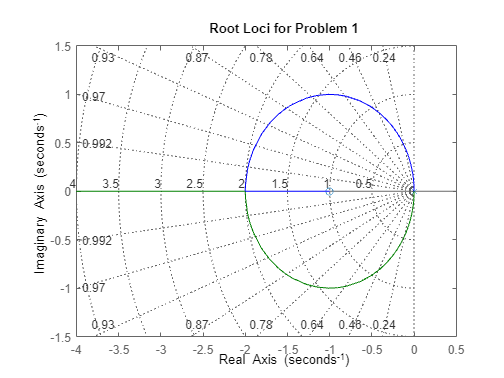

num = [1 1];
den = [1 0 0];
sys = tf(num, den);
rlocus(sys)
grid
title("Root Loci for Problem 1")

## Problem 2: Root Locus

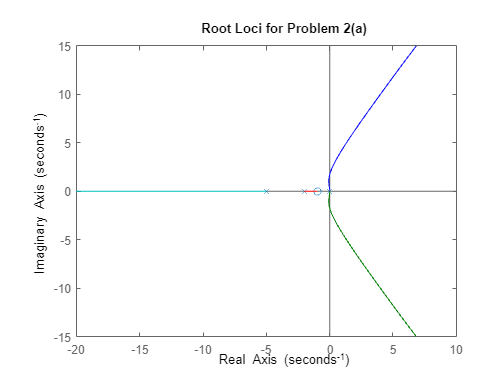

% Problem 2(a): Plot root loci
num = [0 0 0 2 2];
den = [1 7 10 0 0];
sys = tf(num, den);
rlocus(sys)
title("Root Loci for Problem 2(a)")

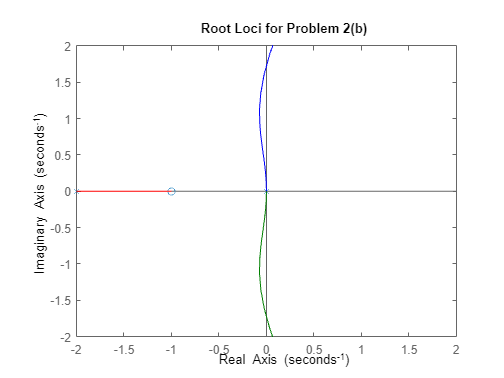

% Problem 2(b): Range of gain K
num = [0 0 0 2 2];
den = [1 7 10 0 0];
sys = tf(num, den);
rlocus(sys)
xlim([-2 2]);
ylim([-2 2]);
title("Root Loci for Problem 2(b)")

## Problem 3: Compensator

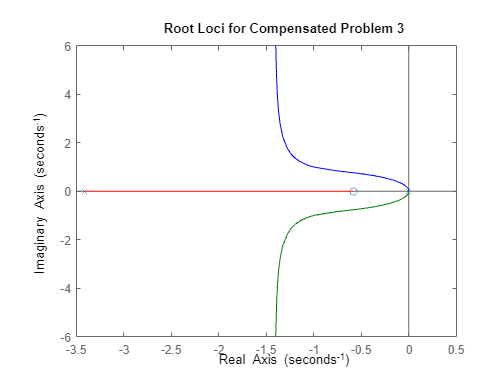

% Problem 3: Plot root loci
num = [0 0 4.8112 2.8184];
den = [1 3.4142 0 0];
sys = tf(num, den);
rlocus(sys)
title("Root Loci for Compensated Problem 3")

## Problem 5: Bode Diagram

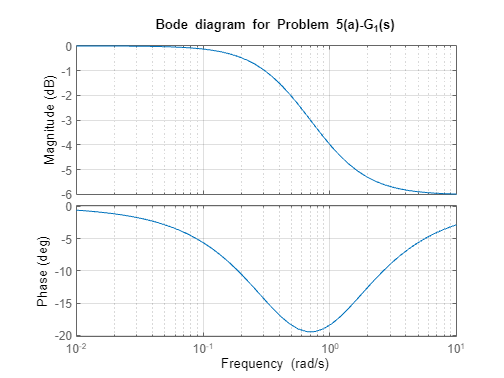

% Problem 5(a) - Minimum phase system
num = [1 1];
den = [2 1];
sys = tf(num, den);
bode(sys)
grid on;
title("Bode diagram for Problem 5(a)-G_1(s)")

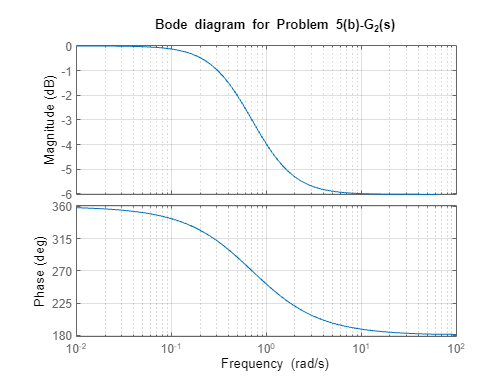

% Problem 5(b) - Non-minimum phase system
num = [-1 1];
den = [2 1];
sys = tf(num, den);
bode(sys)
grid on;
title("Bode diagram for Problem 5(b)-G_2(s)")

## Problem 7: Nyquist Plot

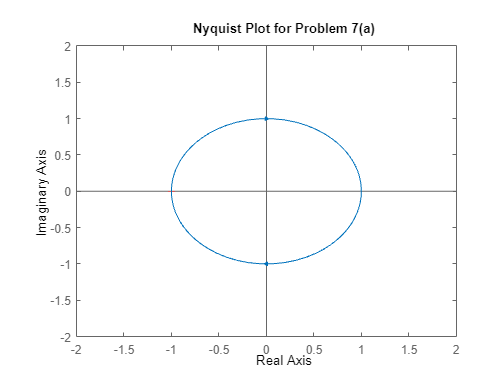

num = [-1 1];
den = [1 1];
sys = tf(num, den);
nyquist(sys)
xlim([-2 2]);
ylim([-2 2]);
title("Nyquist Plot for Problem 7(a)")

## Problem 9: Bode Diagram

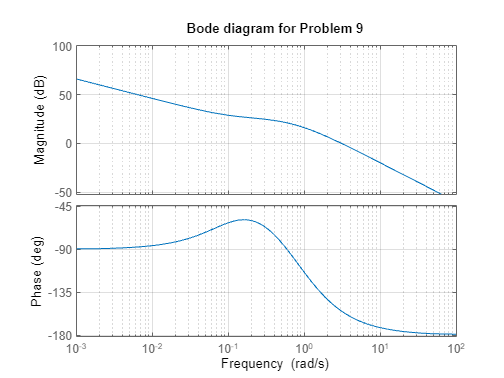

num = [10, 1];
den = [1 1.5 0.5 0];
sys = tf(num, den);
bode(sys)
grid on;
title("Bode diagram for Problem 9")

omega_gc = 1.44024;
K = abs(((0.5+1i*omega_gc)*(1i*omega_gc)*(1+1i*omega_gc))/(10*(0.1+1i*omega_gc)))

K = 0.2667

Phase curve always lies above -180 degrees. Therefore, there exists no phase-cross over frequency. Hence, the gain margin is infinity. 

## Problem 10: PID Control

clc;
clearvars;
close all;
%
t = 0:0.01:10;
k = 0;
for K = 4:-0.05:1
    for a = 4:-0.05:0.4
        num = [0 0 1.2*K 2.4*K*a 1.2*K*a^2];
        den = [0.36 1.86 2.5+1.2*K 1+2.4*K*a 1.2*K*a^2];
        sys = tf(num, den);
        y = step(sys, t);
        m = max(y);
        if m < 1.1 && m > 1.02
            break;
        end
    end
    if m < 1.1 && m > 1.02
        break;
    end
end
% Solution:
disp("K = " + K);

K = 4


disp("a = " + a);

a = 0.7


disp("m = " + m);

m = 1.0846


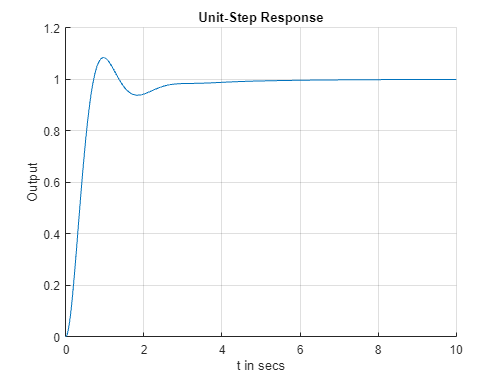

% Plotting
figure(1);
hold on;
grid on;
title("Unit-Step Response");
xlabel("t in secs");
ylabel("Output");
plot(t,y)